# **Generation of a quadrilateral mesh**

It returns a set of points in $X$- and $Y$-Cartesian directions that provide a structured quadrilateral discretization of the rectangular domain $\left\lbrack X_0 ,X_{L_x } \right\rbrack \times \left\lbrack Y_0 ,Y_{L_y } \right\rbrack$:

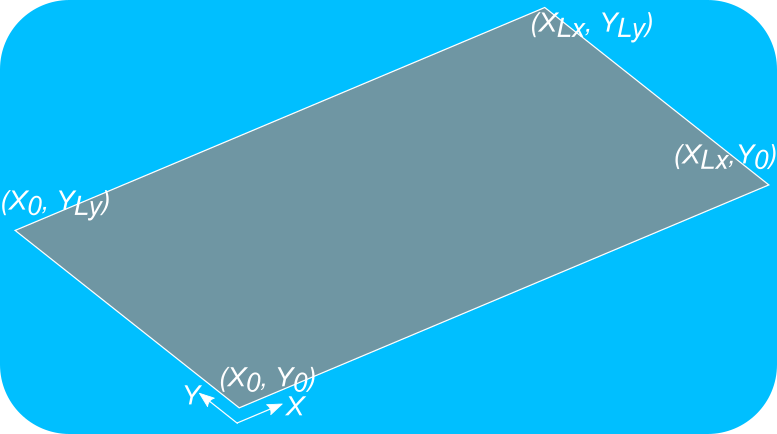

function [nodesX, nodesY] = generateQuadrilateralMesh(X0, XLx, Y0, YLy, numElx, numEly)

## **Function Description**

It returns the Cartesian coordinates of the nodes corresponding to a mesh of a rectangular plate.

**                 Input :**

              `X0`, `XLx` : Start and end coordinates of the computational domain along the $X$-direction

              `Y0`, `YLy` : Start and end coordinates of the computational domain along the $Y$-direction

`numElx`, `numEly` : Number of elements along the x- and the y-directions

**              Output :**

`nodesX`, `nodesY` : $X$- and $Y$-Cartesian coordinates of the nodes in the mesh

## Function Implementation

### Input validation

arguments
    X0 (1, 1) double
    XLx (1, 1) double
    Y0 (1, 1) double
    YLy (1, 1) double
    numElx (1, 1) double {mustBeInteger, mustBePositive}
    numEly (1, 1) double {mustBeInteger, mustBePositive}
end

### Generation of a structured discretization both along *X*- and *Y*-Cartesian directions

isMeshEquispaced = true; % Render the mesh non-equispaced
nodes_alongX = linspace(X0, XLx, numElx + 1)';
nodes_alongY = linspace(Y0, YLy, numEly + 1)';
if ~isMeshEquispaced
    nodes_alongX = [0 0.4 0.9 1.6 2]';
    nodes_alongY = [0 0.6 1]';
end
nodesX = repmat(nodes_alongX, 1, numEly + 1)';
nodesY = repmat(nodes_alongY, numElx + 1, 1);

### Render the mesh non-uniform by modifying some of the nodal coordinates (it only works for `numElx = 4` and `numEly = 2`)

isMeshUniform = true;
if ~isMeshUniform
    if numElx ~= 4 || numEly ~= 2
        error("Making the mesh non-uniform only works for numElx = 4 and numEly = 2")
    end
    % Move node 2
    nodesY(2, 1) = nodesY(2, 1) + 0.08; % y

    % Move node 5
    nodesX(2, 2) = nodesX(2, 2) + 0.08; % x
    nodesY(5, 1) = nodesY(5, 1) - 0.08; % y
    
    % Move node 8
    nodesX(2, 3) = nodesX(2, 3) - 0.08; % x
    nodesY(8, 1) = nodesY(8, 1) + 0.08; % y
    
    % Move node 11
    nodesX(2, 4) = nodesX(2, 4) + 0.08; % x
    nodesY(11, 1) = nodesY(11, 1) + 0.08; % x
    
    % Move node 14
    nodesY(14, 1) = nodesY(14, 1) - 0.08; % x
end

end